dbstop if error

## Train an example FC network to achieve very high classification, fast.

addpath(genpath('./dlt_cnn_map_dropout_nobiasnn'));

## Load data

rand('state', 0);
load mnist_uint8;

train_x = double(train_x) / 255;
test_x  = double(test_x)  / 255;

## Noise

TYPE: none, gaussian, rayleigh, uniform, gamma, pepper

% noise_type = 'uniform';
% snr = '-3db';
% test_x = makenoise(test_x, noise_type, snr);

## Directly Load fnn.mat

load('fnn_2hidden.mat');

## Test Accuracy

[er, bad] = nntest(nn, test_x, test_y);
fprintf('Test Accuracy: %2.2f%%.\n', (1-er)*100);

Test Accuracy: 66.90%.


## Spike-based Testing of Fully-Connected NN

t_opts = struct('t_ref', 0.000, 'reset', 0.0, 'dt', 0.001, 'report_every', 0.001, 'threshold', 1, 'duration', 0.100, 'max_rate', 200);
SFCN = fcnlifsim(nn, test_x, test_y, t_opts);

Time: 0.001s | Accuracy: 10.05%.
Time: 0.002s | Accuracy: 10.05%.
Time: 0.003s | Accuracy: 10.05%.
Time: 0.004s | Accuracy: 10.05%.
Time: 0.005s | Accuracy: 10.05%.
Time: 0.006s | Accuracy: 10.05%.
Time: 0.007s | Accuracy: 10.05%.
Time: 0.008s | Accuracy: 10.05%.
Time: 0.009s | Accuracy: 10.05%.
Time: 0.010s | Accuracy: 10.05%.
Time: 0.011s | Accuracy: 10.05%.
Time: 0.012s | Accuracy: 10.05%.
Time: 0.013s | Accuracy: 10.05%.
Time: 0.014s | Accuracy: 10.05%.
Time: 0.015s | Accuracy: 10.05%.
Time: 0.016s | Accuracy: 10.05%.
Time: 0.017s | Accuracy: 10.05%.
Time: 0.018s | Accuracy: 10.20%.
Time: 0.019s | Accuracy: 10.30%.
Time: 0.020s | Accuracy: 10.95%.
Time: 0.021s | Accuracy: 12.05%.
Time: 0.022s | Accuracy: 14.00%.
Time: 0.023s | Accuracy: 15.95%.
Time: 0.024s | Accuracy: 19.60%.
Time: 0.025s | Accuracy: 24.25%.
Time: 0.026s | Accuracy: 29.60%.
Time: 0.027s | Accuracy: 35.00%.
Time: 0.028s | Accuracy: 39.05%.
Time: 0.029s | Accuracy: 43.15%.
Time: 0.030s | Accuracy: 46.70%.
Time: 0.03

ip_opts = struct('tau', 0.2, 'beta', 0.6, 'sigma', 1, 'learning_rate', 0.05, 'initial_rC', 2, 'initial_rR', 2);
SFCN_IP = fcnlifsim_ip(nn, test_x, test_y, t_opts, ip_opts);

Time: 0.001s | Accuracy: 10.05%.
Time: 0.002s | Accuracy: 10.05%.
Time: 0.003s | Accuracy: 10.20%.
Time: 0.004s | Accuracy: 12.90%.
Time: 0.005s | Accuracy: 20.10%.
Time: 0.006s | Accuracy: 33.90%.
Time: 0.007s | Accuracy: 45.15%.
Time: 0.008s | Accuracy: 52.80%.
Time: 0.009s | Accuracy: 55.95%.
Time: 0.010s | Accuracy: 58.05%.
Time: 0.011s | Accuracy: 60.00%.
Time: 0.012s | Accuracy: 61.65%.
Time: 0.013s | Accuracy: 62.75%.
Time: 0.014s | Accuracy: 62.75%.
Time: 0.015s | Accuracy: 63.50%.
Time: 0.016s | Accuracy: 63.95%.
Time: 0.017s | Accuracy: 64.00%.
Time: 0.018s | Accuracy: 64.60%.
Time: 0.019s | Accuracy: 64.75%.
Time: 0.020s | Accuracy: 64.70%.
Time: 0.021s | Accuracy: 65.20%.
Time: 0.022s | Accuracy: 65.35%.
Time: 0.023s | Accuracy: 65.75%.
Time: 0.024s | Accuracy: 66.10%.
Time: 0.025s | Accuracy: 65.95%.
Time: 0.026s | Accuracy: 66.60%.
Time: 0.027s | Accuracy: 66.65%.
Time: 0.028s | Accuracy: 66.65%.
Time: 0.029s | Accuracy: 66.55%.
Time: 0.030s | Accuracy: 66.85%.
Time: 0.03

% ip_opts = struct('tau', 0.2, 'beta', 0.6, 'sigma', 1, 'learning_rate', 0.05, 'initial_rC', 2, 'initial_rR', 2);
% SFCN_IP_S2 = fcnlifsim_ip_S2(nn, test_x, test_y, t_opts, ip_opts);

ip_opts = struct('tau', 0.2, 'beta', 0.6, 'sigma', 1, 'learning_rate', 0.05, 'initial_rC', 2, 'initial_rR', 2);
SFCN_INPUT_DRIVEN_IP = fcnlifsim_input_driven_ip(nn, test_x, test_y, t_opts, ip_opts);

Time: 0.001s | Accuracy: 10.05%.
Time: 0.002s | Accuracy: 10.05%.
Time: 0.003s | Accuracy: 10.40%.
Time: 0.004s | Accuracy: 12.75%.
Time: 0.005s | Accuracy: 20.85%.
Time: 0.006s | Accuracy: 34.30%.
Time: 0.007s | Accuracy: 43.10%.
Time: 0.008s | Accuracy: 49.65%.
Time: 0.009s | Accuracy: 53.85%.
Time: 0.010s | Accuracy: 56.35%.
Time: 0.011s | Accuracy: 58.25%.
Time: 0.012s | Accuracy: 59.85%.
Time: 0.013s | Accuracy: 61.00%.
Time: 0.014s | Accuracy: 61.45%.
Time: 0.015s | Accuracy: 62.15%.
Time: 0.016s | Accuracy: 62.75%.
Time: 0.017s | Accuracy: 63.15%.
Time: 0.018s | Accuracy: 63.00%.
Time: 0.019s | Accuracy: 63.40%.
Time: 0.020s | Accuracy: 63.65%.
Time: 0.021s | Accuracy: 64.00%.
Time: 0.022s | Accuracy: 64.25%.
Time: 0.023s | Accuracy: 64.30%.
Time: 0.024s | Accuracy: 64.65%.
Time: 0.025s | Accuracy: 64.95%.
Time: 0.026s | Accuracy: 65.35%.
Time: 0.027s | Accuracy: 65.80%.
Time: 0.028s | Accuracy: 65.95%.
Time: 0.029s | Accuracy: 66.20%.
Time: 0.030s | Accuracy: 66.30%.
Time: 0.03

ip_opts = struct('tau', 0.001, 'beta', 0.6, 'sigma', 0.5, 'learning_rate', 1, 'initial_rC', 1, 'initial_rR', 2);
SFCN_SELF_DRIVEN_IP = fcnlifsim_self_driven_ip(nn, test_x, test_y, t_opts, ip_opts);

Time: 0.001s | Accuracy: 10.05%.
Time: 0.002s | Accuracy: 10.05%.
Time: 0.003s | Accuracy: 10.40%.
Time: 0.004s | Accuracy: 13.85%.
Time: 0.005s | Accuracy: 21.65%.
Time: 0.006s | Accuracy: 36.35%.
Time: 0.007s | Accuracy: 46.35%.
Time: 0.008s | Accuracy: 51.80%.
Time: 0.009s | Accuracy: 54.85%.
Time: 0.010s | Accuracy: 56.95%.
Time: 0.011s | Accuracy: 58.85%.
Time: 0.012s | Accuracy: 60.15%.
Time: 0.013s | Accuracy: 60.85%.
Time: 0.014s | Accuracy: 61.55%.
Time: 0.015s | Accuracy: 61.95%.
Time: 0.016s | Accuracy: 62.00%.
Time: 0.017s | Accuracy: 62.45%.
Time: 0.018s | Accuracy: 63.05%.
Time: 0.019s | Accuracy: 63.65%.
Time: 0.020s | Accuracy: 63.75%.
Time: 0.021s | Accuracy: 63.55%.
Time: 0.022s | Accuracy: 63.75%.
Time: 0.023s | Accuracy: 64.00%.
Time: 0.024s | Accuracy: 64.35%.
Time: 0.025s | Accuracy: 64.35%.
Time: 0.026s | Accuracy: 64.45%.
Time: 0.027s | Accuracy: 64.85%.
Time: 0.028s | Accuracy: 65.20%.
Time: 0.029s | Accuracy: 65.10%.
Time: 0.030s | Accuracy: 65.20%.
Time: 0.03

## Show the difference

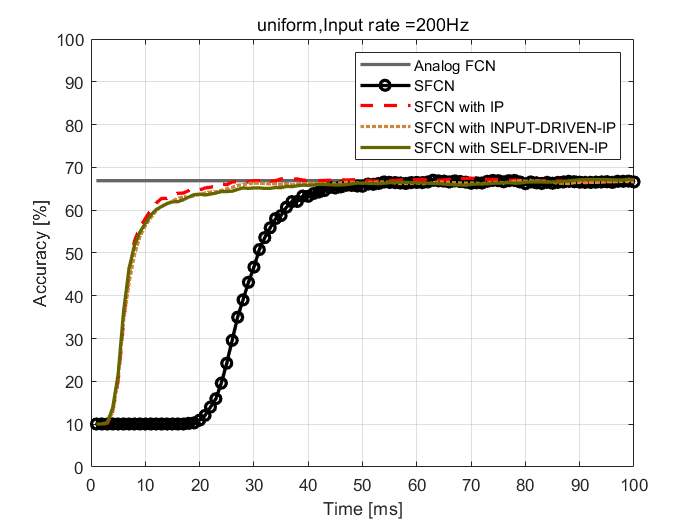

figure;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SFCN.performance,'color','black','linewidth',2, 'LineStyle','-', 'Marker','o');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SFCN_IP.performance,'color',[1,0,0],'linewidth',2, 'LineStyle','--', 'Marker','none');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SFCN_INPUT_DRIVEN_IP.performance,'color',[0.8039,0.5216,0.2471],'linewidth',2, 'LineStyle',':', 'Marker','none');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SFCN_SELF_DRIVEN_IP.performance,'color',[0.4,0.4,0],'linewidth',2, 'LineStyle','-', 'Marker','none');
legend('SFCN', 'SFCN with IP', 'SFCN with INPUT-DRIVEN-IP', 'SFCN with SELF-DRIVEN-IP');
ylim([00 100]);
xlabel('Time [ms]');
ylabel('Accuracy [%]');
title(strcat('Input rate = ', num2str(t_opts.max_rate), 'Hz'));
grid();

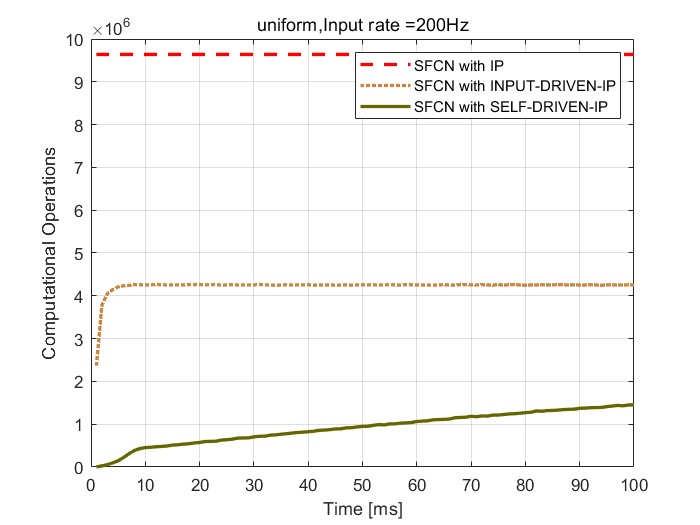

figure(); clf;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SFCN_IP.computational_operations,'color',[1,0,0],'linewidth',2, 'LineStyle','--', 'Marker','none');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SFCN_INPUT_DRIVEN_IP.computational_operations,'color',[0.8039,0.5216,0.2471],'linewidth',2, 'LineStyle',':', 'Marker','none');
hold on;
plot(1:1:ceil(t_opts.duration/t_opts.dt), SFCN_SELF_DRIVEN_IP.computational_operations,'color',[0.4,0.4,0],'linewidth',2, 'LineStyle','-', 'Marker','none');
legend('SFCN with IP', 'SFCN with INPUT-DRIVEN-IP', 'SFCN with SELF-DRIVEN-IP');
xlabel('Time [ms]');
ylabel('Computational Operations');
title(strcat('Input rate = ', num2str(t_opts.max_rate), 'Hz'));
grid();